clear;
clc;
close all;

R = 10;
L = 0.01;
C = 1e-6;

f = logspace(0, 6, 2000);
w = 2*pi*f;
Z = R + 1j*w*L + 1./(1j*w*C)

Z = 1.0e+05 *

   0.0001 - 1.5915i   0.0001 - 1.5806i   0.0001 - 1.5697i   0.0001 - 1.5589i   0.0001 - 1.5482i   0.0001 - 1.5375i   0.0001 - 1.5269i   0.0001 - 1.5164i   0.0001 - 1.5059i   0.0001 - 1.4956i   0.0001 - 1.4853i   0.0001 - 1.4750i   0.0001 - 1.4649i   0.0001 - 1.4548i   0.0001 - 1.4448i   0.0001 - 1.4348i   0.0001 - 1.4249i   0.0001 - 1.4151i   0.0001 - 1.4054i   0.0001 - 1.3957i   0.0001 - 1.3861i   0.0001 - 1.3765i   0.0001 - 1.3671i   0.0001 - 1.3576i   0.0001 - 1.3483i   0.0001 - 1.3390i   0.0001 - 1.3298i   0.0001 - 1.3206i   0.0001 - 1.3115i   0.0001 - 1.3025i   0.0001 - 1.2935i   0.0001 - 1.2846i   0.0001 - 1.2758i   0.0001 - 1.2670i   0.0001 - 1.2583i   0.0001 - 1.2496i   0.0001 - 1.2410i   0.0001 - 1.2324i   0.0001 - 1.2239i   0.0001 - 1.2155i   0.0001 - 1.2071i   0.0001 - 1.1988i   0.0001 - 1.1906i   0.0001 - 1.1824i   0.0001 - 1.1742i   0.0001 - 1.1661i   0.0001 - 1.1581i   0.0001 - 1.1501i   0.0001 - 1.1422i   0.0001 - 1.1343i


mag = abs(Z)

mag = 1.0e+05 *

    1.5915    1.5806    1.5697    1.5589    1.5482    1.5375    1.5269    1.5164    1.5059    1.4956    1.4853    1.4750    1.4649    1.4548    1.4448    1.4348    1.4249    1.4151    1.4054    1.3957    1.3861    1.3765    1.3671    1.3576    1.3483    1.3390    1.3298    1.3206    1.3115    1.3025    1.2935    1.2846    1.2758    1.2670    1.2583    1.2496    1.2410    1.2324    1.2239    1.2155    1.2071    1.1988    1.1906    1.1824    1.1742    1.1661    1.1581    1.1501    1.1422    1.1343


phase = angle(Z)*180/pi

phase =   -89.9964  -89.9964  -89.9963  -89.9963  -89.9963  -89.9963  -89.9962  -89.9962  -89.9962  -89.9962  -89.9961  -89.9961  -89.9961  -89.9961  -89.9960  -89.9960  -89.9960  -89.9960  -89.9959  -89.9959  -89.9959  -89.9958  -89.9958  -89.9958  -89.9958  -89.9957  -89.9957  -89.9957  -89.9956  -89.9956  -89.9956  -89.9955  -89.9955  -89.9955  -89.9954  -89.9954  -89.9954  -89.9954  -89.9953  -89.9953  -89.9953  -89.9952  -89.9952  -89.9952  -89.9951  -89.9951  -89.9951  -89.9950  -89.9950  -89.9949


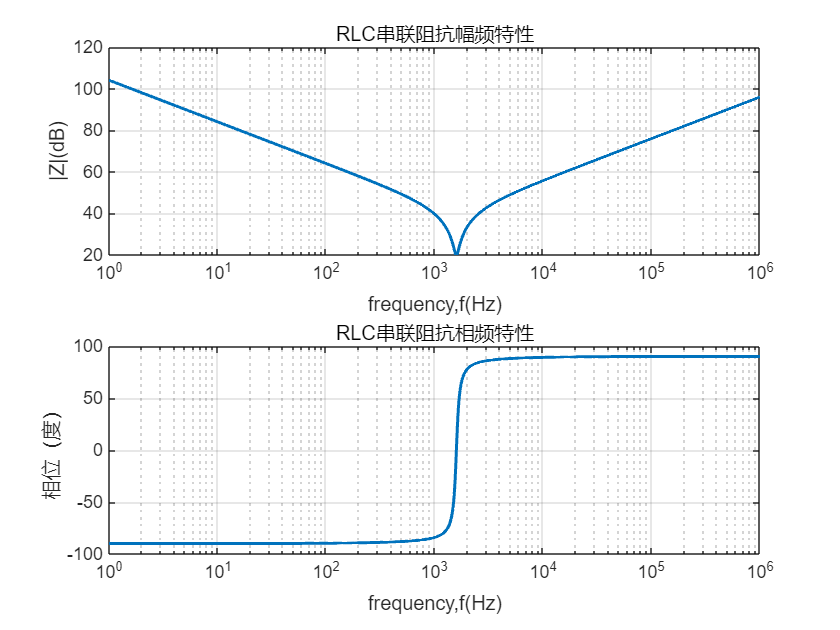

figure;
subplot(2,1,1)
semilogx(f, 20*log10(mag),'LineWidth',1.5)
grid on 
xlabel('frequency,f(Hz)')
ylabel('|Z|(dB)')
title('RLC串联阻抗幅频特性')

subplot(2,1,2)
semilogx(f, phase, 'LineWidth',1.5)
grid on 
xlabel('frequency,f(Hz)')
ylabel('相位（度）')
title('RLC串联阻抗相频特性')